# "Vanilla" SINDy limitations / challenges 

- **Data**: noise level, amount of data, sampling rate

- **Model selection**: hyperparameter lambda

- **Library**: polynomials, trigonometric functions

- This tutorial is using Lorenz system dynamics: 

                     
$$\begin{array}{l}
\dot{x} =\sigma \;\left(y-x\right)\\
\dot{y} =x\left(\rho -z\right)-y\\
\dot{z} =\textrm{xy}-\beta \;z
\end{array}$$


# 1. Data: noise level, amount of data, sampling rate

param = [10; 28; 8/3]; % Lorenz system parameters (chaotic)
n = 3; % number of states
x0 = [-8; 8; 27];  % Initial condition
dt = 0.001; % time step
tFinal = 20; % final time
tspan = dt:dt:tFinal;
options = odeset('RelTol',1e-12,'AbsTol',1e-12*ones(1,3));
[t,x]=ode45(@(t,x) lorenz(t,x,param),tspan,x0,options);


% Add Gaussian white noise
rng(1)
sig =0.01; % noise level
x = x + sig*std(x(:))*randn(size(x));


% Compute Derivative: finite difference
dx = (1/(12*dt))*(-x(5:end,:)+8*x(4:end-1,:)-8*x(2:end-3,:)+x(1:end-4,:)); % fourth order central difference
x = x(3:end-2,:); % cut tails


% Pool Data (i.e., build library of nonlinear time series)
polyorder = 3; % polynomials up to order 3
Theta = poolData(x,n,polyorder);
m = size(Theta,2); % size of library


% Compute Sparse regression: sequential least squares
lambda = 0.1;      % lambda is our sparsification knob.
Xi = sparsifyDynamics(Theta,dx,lambda,n); % identify model coefficients
disp('Test noise and data sensitivity')

Test noise and data sensitivity


disp(poolDataLIST({'x','y','z'},Xi,n,polyorder)) % display SINDy model

    {0×0 char}    {'xdot'   }    {'ydot'   }    {'zdot'   }
    {'1'     }    {[      0]}    {[      0]}    {[      0]}
    {'x'     }    {[-9.9810]}    {[27.8203]}    {[      0]}
    {'y'     }    {[ 9.9855]}    {[-0.9457]}    {[      0]}
    {'z'     }    {[      0]}    {[      0]}    {[-2.6649]}
    {'xx'    }    {[      0]}    {[      0]}    {[      0]}
    {'xy'    }    {[      0]}    {[      0]}    {[ 0.9992]}
    {'xz'    }    {[      0]}    {[-0.9958]}    {[      0]}
    {'yy'    }    {[      0]}    {[      0]}    {[      0]}
    {'yz'    }    {[      0]}    {[      0]}    {[      0]}
    {'zz'    }    {[      0]}    {[      0]}    {[      0]}
    {'xxx'   }    {[      0]}    {[      0]}    {[      0]}
    {'xxy'   }    {[      0]}    {[      0]}    {[      0]}
    {'xxz'   }    {[      0]}    {[      0]}    {[      0]}
    {'xyy'   }    {[      0]}    {[      0]}    {[      0]}
    {'xyz'   }    {[      0]}    {[      0]}    {[      0]}
    {'xzz'   }    {[      0]}    {[     

# 2. Model selection: hyperparameter$\lambda$ 

## Sweep over lambda, starting from LS solution ($\lambda =0$)

lambdaP = -4; 
lambda = 10^lambdaP; % lambda is our sparsification knob.
Xi = sparsifyDynamics(Theta,dx,lambda,n); % identify model coefficients
disp('Test hyperparameter sensitivity')

Test hyperparameter sensitivity


disp(poolDataLIST({'x','y','z'},Xi,n,polyorder)) % display SINDy model

    {0×0 char}    {'xdot'       }    {'ydot'   }    {'zdot'       }
    {'1'     }    {[    -0.4205]}    {[ 3.6672]}    {[    -0.7664]}
    {'x'     }    {[   -10.5393]}    {[25.5403]}    {[     2.3530]}
    {'y'     }    {[    10.4060]}    {[ 0.6260]}    {[    -1.2774]}
    {'z'     }    {[    -0.1123]}    {[-1.0260]}    {[    -2.5061]}
    {'xx'    }    {[     0.1732]}    {[-0.0113]}    {[-6.7701e-04]}
    {'xy'    }    {[    -0.3324]}    {[-0.1553]}    {[     0.9581]}
    {'xz'    }    {[     0.1872]}    {[-0.8373]}    {[    -0.1249]}
    {'yy'    }    {[     0.1269]}    {[ 0.0849]}    {[     0.0256]}
    {'yz'    }    {[    -0.1021]}    {[-0.1272]}    {[     0.0646]}
    {'zz'    }    {[     0.0212]}    {[ 0.0784]}    {[    -0.0122]}
    {'xxx'   }    {[     0.0289]}    {[ 0.0055]}    {[ 1.5950e-04]}
    {'xxy'   }    {[    -0.0274]}    {[-0.0169]}    {[     0.0023]}
    {'xxz'   }    {[-9.6916e-04]}    {[ 0.0054]}    {[    -0.0013]}
    {'xyy'   }    {[     0.0087]}    {[ 0.0111]}

# 3. Library: polynomials, trigonometric functions, ... 

## Generate Data - inverted pendulum

paramP.m = 0.1; % mass     
paramP.l = 0.5; % arm length
paramP.k = 0.03; % friction coefficient
paramP.g = 9.8; % gravity
n = 2; % number of states
dt = 0.001; % time step
tspan = dt:dt:20;
forcing = @(x,t) 0; % pendulum forcing
x0=[0.1;0];  % Initial condition: close to upright position
options = odeset('RelTol',1e-12,'AbsTol',1e-12*ones(1,n));
[t,x]=ode45(@(t,x) pendulumODE(t,x,forcing(x,t),paramP),tspan,x0,options);

% Add Gaussian white noise
rng(1)
sig = 0.0;  
x = x + sig*std(x(:))*randn(size(x));

disp('Pendulum time series data')

Pendulum time series data


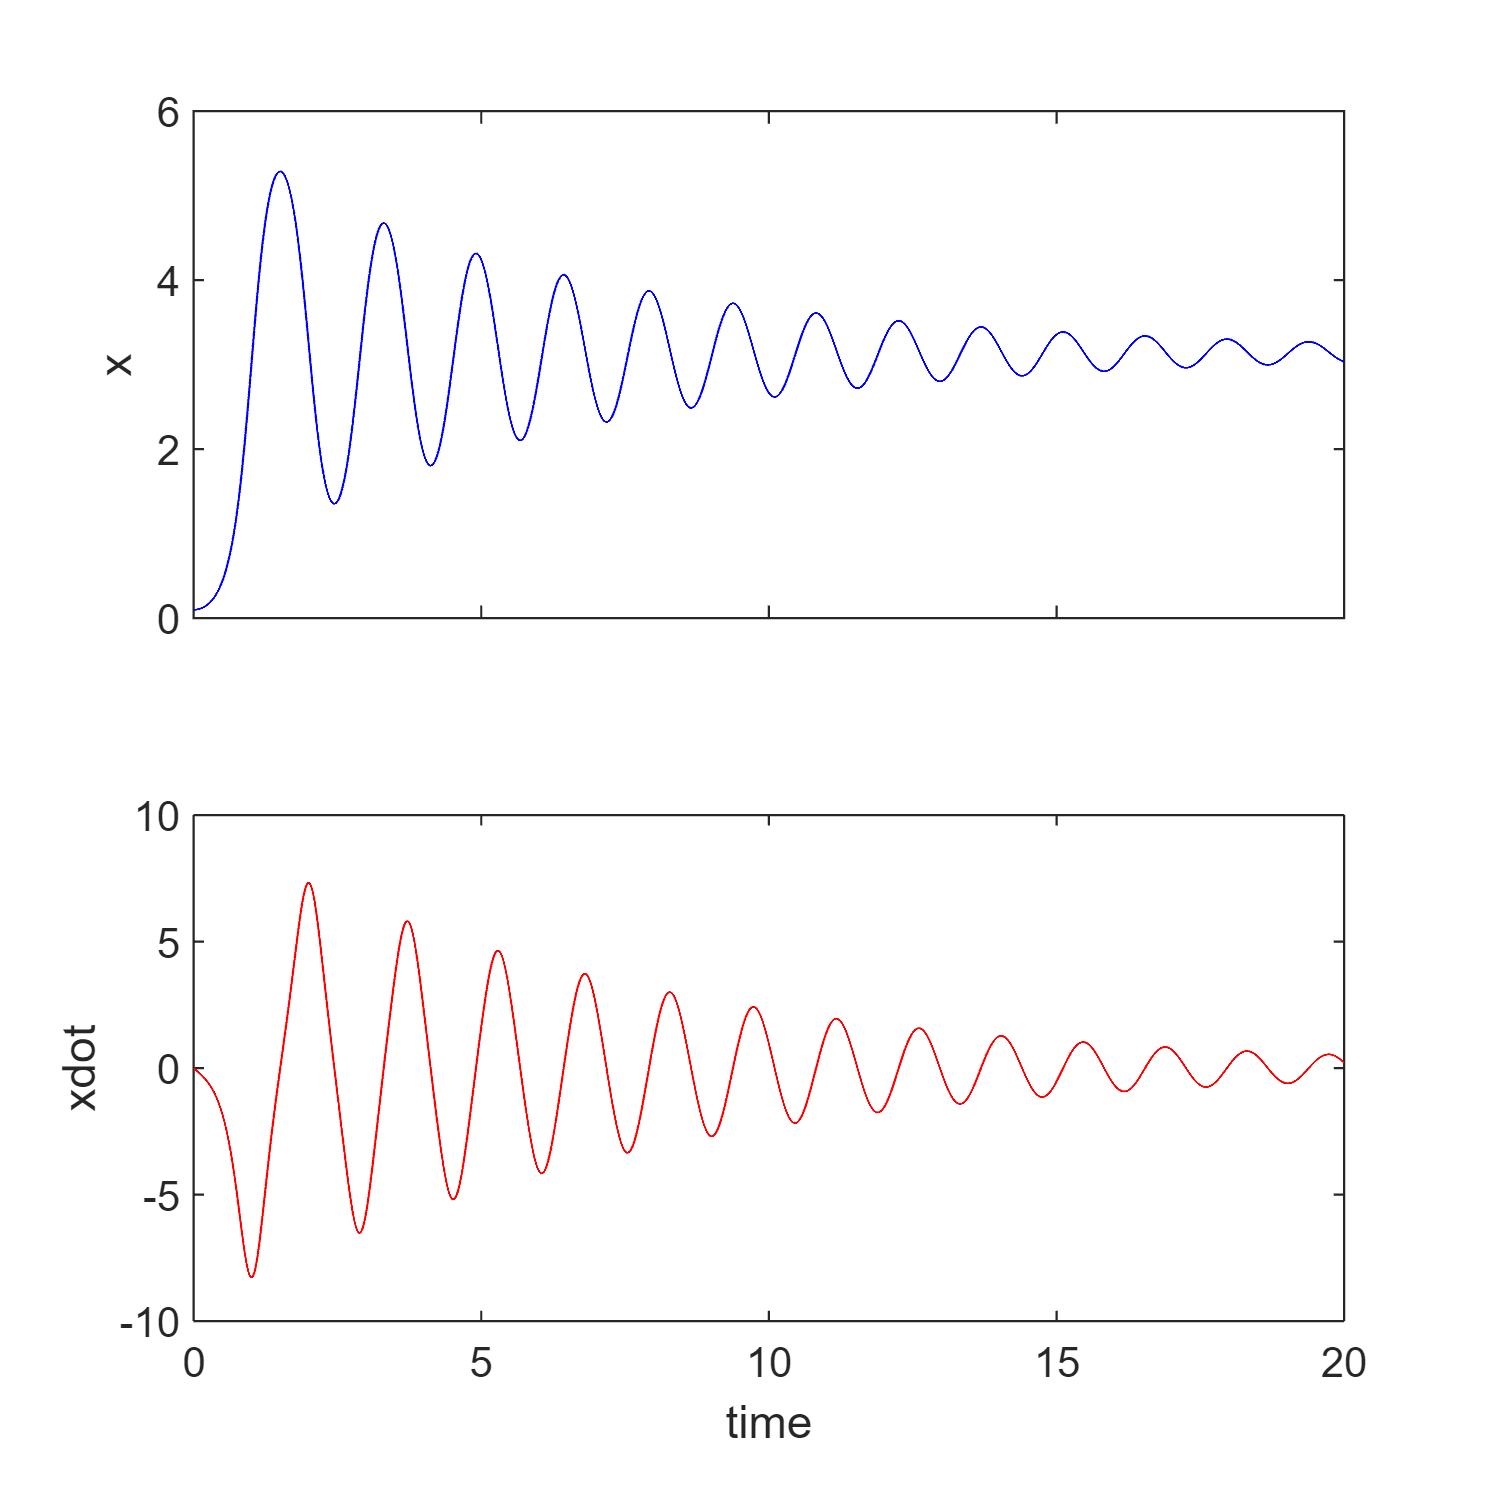

plotPendulum(t,x) % plot data

## Compute Derivative: finite difference

dx = (1/(12*dt))*(-x(5:end,:)+8*x(4:end-1,:)-8*x(2:end-3,:)+x(1:end-4,:)); % fourth order central difference
x = x(3:end-2,:); % cut tails
t = t(3:end-2,:);

## Pool Data (i.e., build library of nonlinear time series)

polyorder = 3; % polynomials up to order 3
Theta = poolData(x,n,polyorder);

## Compute Sparse regression: sequential least squares

lambda = 0.025;      % lambda is our sparsification knob.
Xi = sparsifyDynamics(Theta,dx,lambda,n); % identify model coefficients
disp('Pendulum polynomial library')

Pendulum polynomial library


disp(poolDataLIST({'x','xD'},Xi,n,polyorder)) % display SINDy model

    {0×0 char}    {'xdot'   }    {'xDdot'   }
    {'1'     }    {[      0]}    {[  3.6361]}
    {'x'     }    {[      0]}    {[-41.0819]}
    {'xD'    }    {[-1.0000]}    {[ -1.4304]}
    {'xx'    }    {[      0]}    {[ 19.2567]}
    {'xxD'   }    {[      0]}    {[  0.6813]}
    {'xDxD'  }    {[      0]}    {[       0]}
    {'xxx'   }    {[      0]}    {[ -2.0809]}
    {'xxxD'  }    {[      0]}    {[ -0.0980]}
    {'xxDxD' }    {[      0]}    {[       0]}
    {'xDxDxD'}    {[      0]}    {[       0]}



##  Use SINDy model for prediction

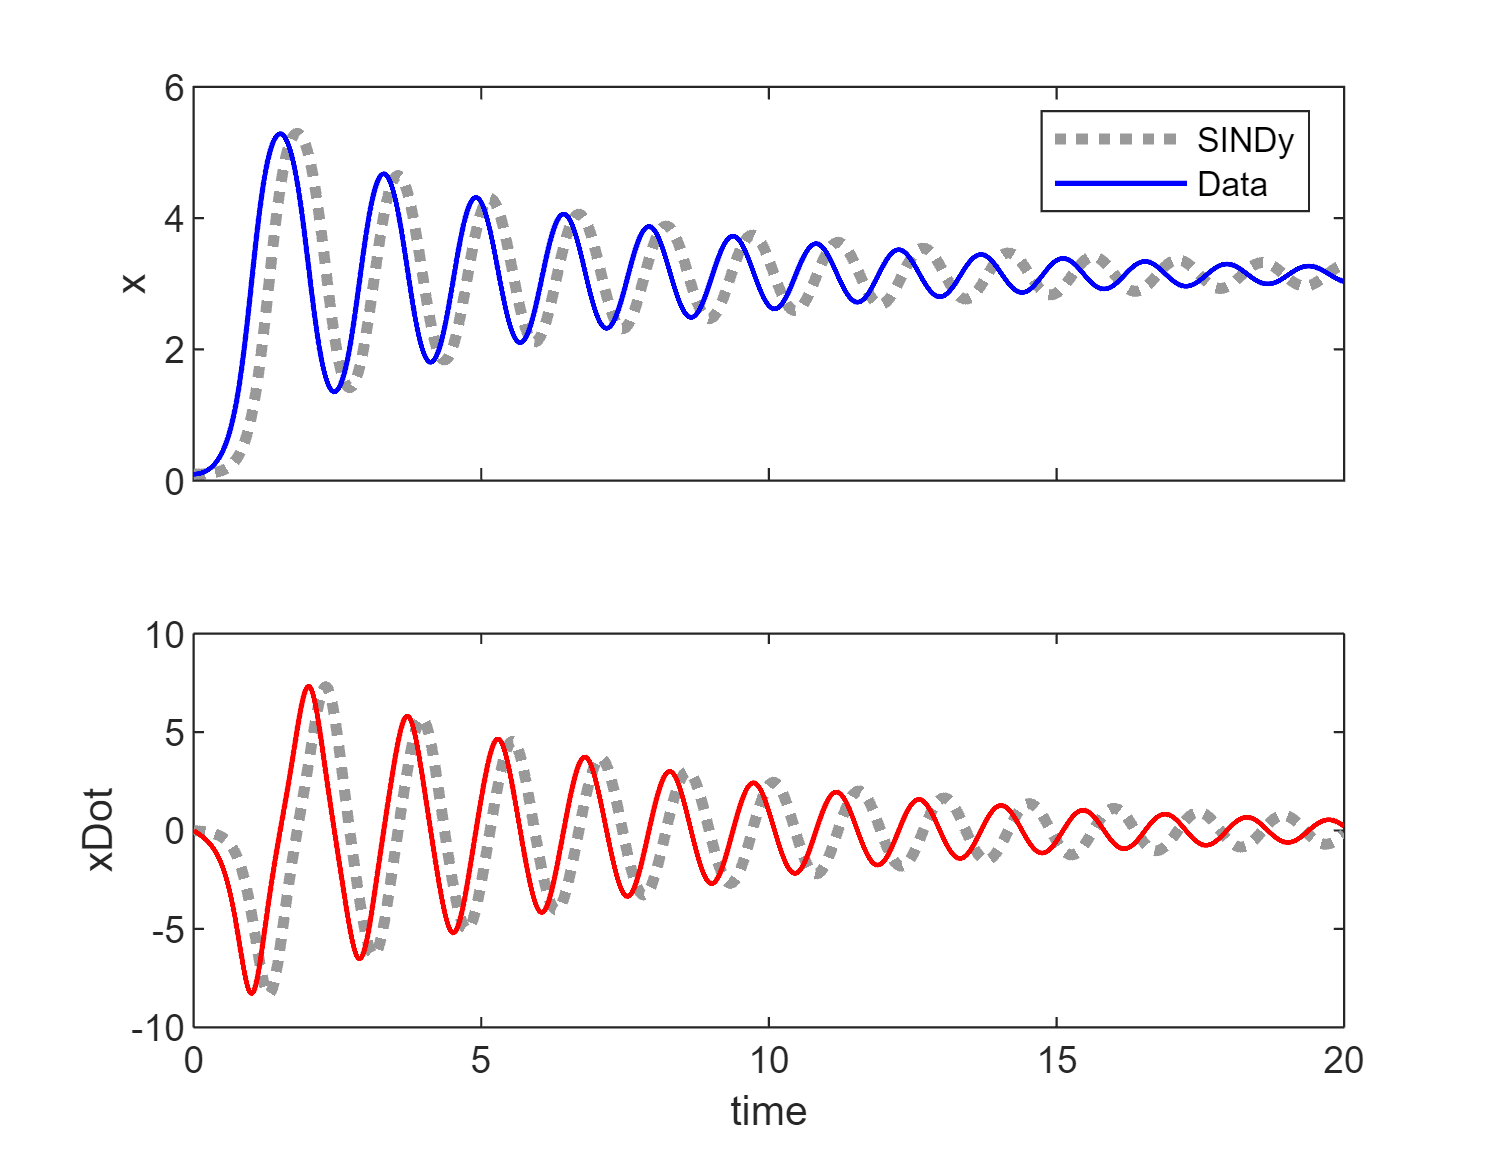

paramSINDy.Xi = Xi;
paramSINDy.polyorder = polyorder;
[tSINDy,xSINDy]=ode45(@(t,x) SINDyODE(t,x,paramSINDy),tspan,x0,options);

plotSINDyPendulum(t,x,tSINDy(3:end-2,:),xSINDy(3:end-2,:)) 

## Use trigonometric functions in library

% build library
polyorder = 3; % polynomials up to order 3
usesine = 1;
sineorder = 2;
Theta = poolDataSine(x,n,polyorder,usesine,sineorder);
m = size(Theta,2); % size of library

% identify SINDy model
lambda = 0.25;      % lambda is our sparsification knob.
Xi = sparsifyDynamics(Theta,dx,lambda,n); % identify model coefficients
disp('Pendulum polynomial and trig library')

Pendulum polynomial  and trig library


disp(poolDataLISTsine({'x','xD'},Xi,n,polyorder,usesine,sineorder)) % display SINDy model

    {0×0 char   }    {'xdot'   }    {'xDdot'   }
    {'1'        }    {[      0]}    {[       0]}
    {'x'        }    {[      0]}    {[       0]}
    {'xD'       }    {[-1.0000]}    {[ -0.3000]}
    {'xx'       }    {[      0]}    {[       0]}
    {'xxD'      }    {[      0]}    {[       0]}
    {'xDxD'     }    {[      0]}    {[       0]}
    {'xxx'      }    {[      0]}    {[       0]}
    {'xxxD'     }    {[      0]}    {[       0]}
    {'xxDxD'    }    {[      0]}    {[       0]}
    {'xDxDxD'   }    {[      0]}    {[       0]}
    {'sin(1*x)' }    {[      0]}    {[-19.6000]}
    {'sin(1*xD)'}    {[      0]}    {[       0]}
    {'cos(1*x)' }    {[      0]}    {[       0]}
    {'cos(1*xD)'}    {[      0]}    {[       0]}
    {'sin(2*x)' }    {[      0]}    {[       0]}
    {'sin(2*xD)'}    {[      0]}    {[       0]}
    {'cos(2*x)' }    {[      0]}    {[       0]}
    {'cos(2*xD)'}    {[      0]}    {[       0]}



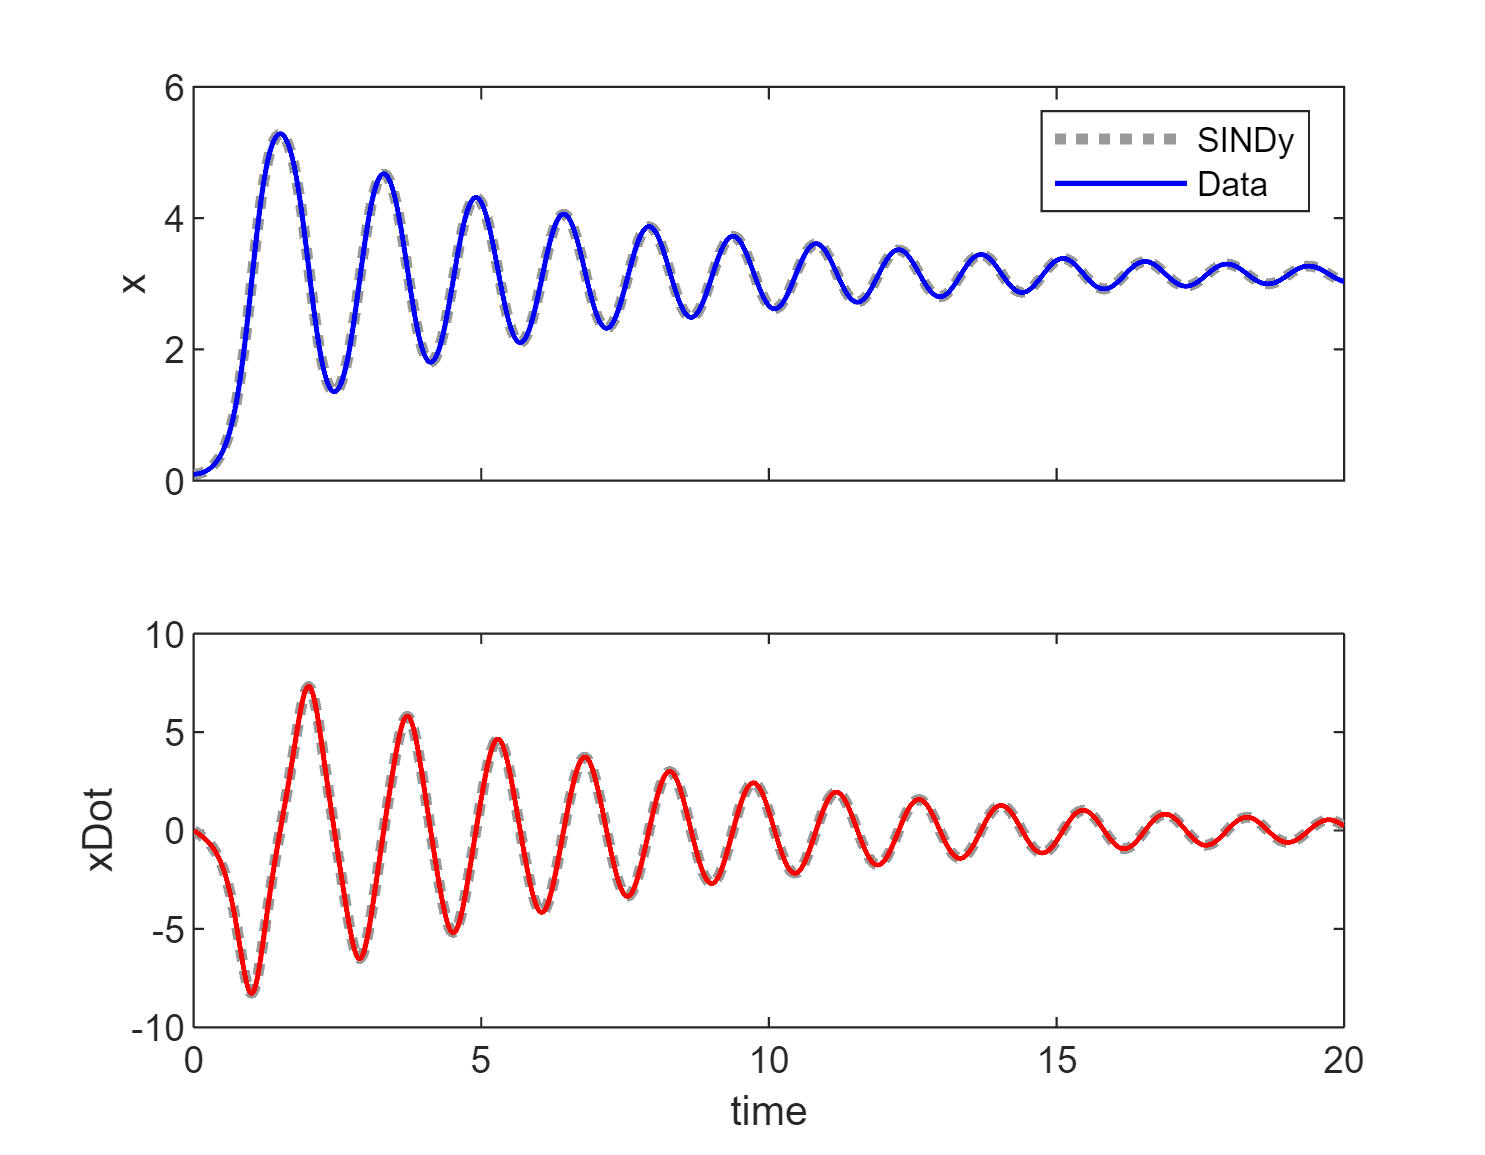

% SINDy model prediction
paramSINDy.Xi = Xi;
paramSINDy.polyorder = polyorder;
paramSINDy.usesine = usesine;
paramSINDy.sineorder = sineorder;
[tSINDy,xSINDy]=ode45(@(t,x) SINDyODEsine(t,x,paramSINDy),tspan,x0,options);

plotSINDyPendulum(t,x,tSINDy(3:end-2,:),xSINDy(3:end-2,:))